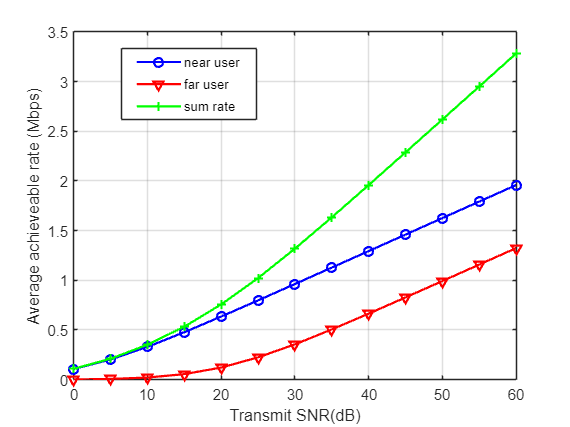

clc; clear variables; close all;

%sum rate for near user and far user with SWIPT, NOMA, C-NOMA SWIPT 
%source, 2 users. strong user acts as energy harvesting 
%relay to weak.  have direct path from BS to far user


N = 10^6;   

dsn = 1;   %Source to near user distance    
dsf = 9;   %Source to far user distance
dnf = dsf - dsn; %Near user to far user distance
eta = 2;    %Path loss exponent
%Rayleigh fading coefficients
hsn = (randn(1,N)+1i*randn(1,N))/sqrt(2) ;
gsn = ((abs(hsn)).^2);
hsf = (randn(1,N)+1i*randn(1,N))/sqrt(2);
gsf = ((abs(hsf)).^2);
hnf = (randn(1,N)+1i*randn(1,N))/sqrt(2);
gnf = ((abs(hnf)).^2);



Pt = 0:5:60;    % 发送功率（dBm）
pt =  10.^(Pt/10);    % 发送功率（线性尺度）mW
B = 1000000;             %bandwidth 1 MHz
B1 = B/2;               %bandwidth for swipt oma
N0_dBm=-60;                % Noise special density  (in dBm/Hz)
N0=(10^(N0_dBm/10))*B;          % Linear noise in mW
N01 = (10^(N0_dBm/10))*B1;      %linear noise for swipt oma
snr = pt/N0;       %SNR in linear
snr1 = pt/(N01);       %SNR in linear(swipt oma)
SNR = 10*log10(snr);%SNR in dB

%Power allocation factors
af = 0.8; an = 0.2;
R1 = 0.3; %Target rate for far user
t1 = (2^(2*R1))-1;   %target snr for both users
R2 = 1;   %target rate for near user
t2 = (2^(2*R2))-1;
eff = 0.7;  %power harvesting efficiency of the near user
frac = 0.3; %power splitting coefficient
del = 10^-6; %a small number

%Some buffers
pn = zeros(1,length(pt));
pf = zeros(1,length(pt));

cn = zeros(1,length(pt));
cf = zeros(1,length(pt));
cph = zeros(1,length(pt));
rsum = zeros(1,length(pt));
csn = zeros(1,length(pt));
cfs = zeros(1,length(pt));
cnc = zeros(1,length(pt));
cfc = zeros(1,length(pt));
cfcn = zeros(1,length(pt));
cfcf = zeros(1,length(pt));
sum_s = zeros(1,length(pt));
sum_n = zeros(1,length(pt));
sum_cn = zeros(1,length(pt));


for u = 1:length(pt)    
   
    

    %Amount of power harvested by near user
    ph = snr1(u)*gsn.*frac*eff/(dsn^eta);
    

    %SNIR for each user
    
    sSNRn = (1-frac)*snr1(u).*gsn./(dsn^eta);   %near user, swipt SNR
    sSNRf = (1-frac)*snr1(u).*gsf./(dsf^eta);
   
    %Achievable rate of near user
 
    Rsn = 0.5*0.2*log2(1 + sSNRn);    %data rate for near user, swipt
  
    %Achievable rate of far user
 
    Rfs= 0.5*0.2*log2(1 + sSNRf);       %data rate for far user, swipt
 
    


    %calculate average rate for each user and the sum rate
 
    csn(u) = mean(Rsn);%swipt near
    cfs(u) = mean(Rfs);%swipt far
 

  
    sum_s(u) = csn(u) + cfs(u);%sum rate swipt
 
    
    

    
end

poutn1 = pn/N;
poutf1 = min(pf/N,1);



figure;
plot(Pt, csn, 'b-o', 'LineWidth', 1.5, 'MarkerSize', 6); hold on; grid on; 
plot(Pt, cfs, 'r-v', 'LineWidth', 1.5, 'MarkerSize', 6); hold on; grid on;
plot(Pt, sum_s, 'g-+', 'LineWidth', 1.5, 'MarkerSize', 6); hold on; grid on;
legend('near user','far user','sum rate');
xlabel('Transmit SNR(dB)');
ylabel('Average achieveable rate (Mbps)');

legend("Position", [0.213,0.71813,0.23689,0.16969])